% Some constants
g=340; % Gravity on the planet Docbrown (ft/s^2)

ti=0;                                       % Start time
tf=10;                                      % End time

syms t;                                     % Symbolic placeholder for time (in minutes)

% Initialize all vector functions
fx = 10*sin(t)+5*sin(5*t)+2.5*sin(2.3*t);
fy = 10*cos(t)+5*cos(5*t)+2.5*cos(2.3*t);
fz = 0.001*t.^4*(1+(cos(2*pi*t).^2));

% Initialize all vectored differentials
r = [fx, fy, fz];
v = diff(r);
a = diff(v);
aunit=a/norm(a);                            % need this for problem 7
anormal = (norm(cross(v, a)))/norm(v);      % Normal component of acceleration

% Initialize some future vectored functions
T=diff(v)/norm(diff(v));
N=diff(T)/norm(diff(T));
B=cross(T,N);

torsion=(dot(-N, B));
curvature=norm(cross(v,a))/norm(v).^3;

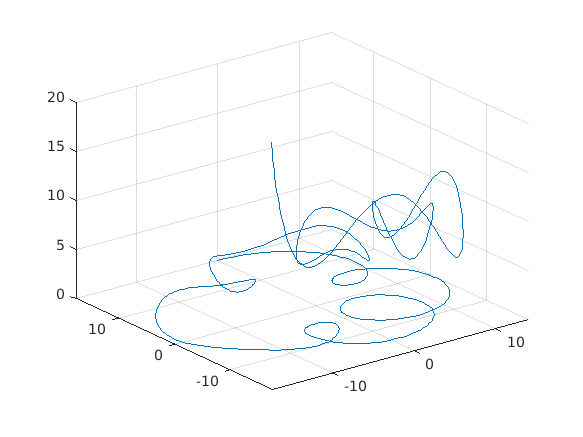

% Question 1
% TODO add the dots and stuff
fplot3(fx, fy, fz, [0,10]);

% Question 2
AbsoluteDistance=vpa(norm(subs(r,t,0) - subs(r,t,10)))

$$AbsoluteDistance = 31.309805687016783893061490631313$$

% Question 3
%normvel=(v(:,1).^2 + v(:,2).^2 + v(:,3).^2).^(1/2);
%T = taylor(normvel, "Order", 10, "ExpansionPoint", 0);
displacement=vpaintegral(norm(v), t, [0,10])

$$displacement = 299.152$$

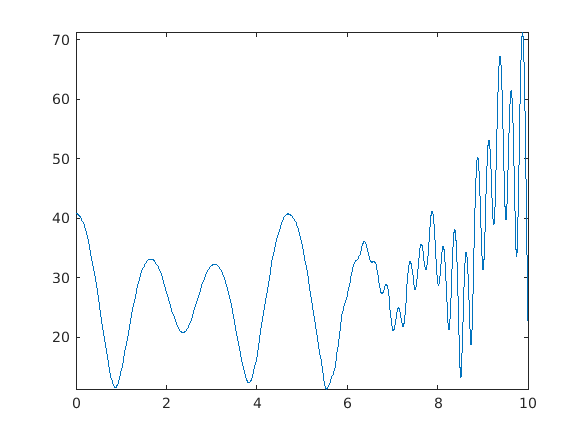

%Question 4
% TODO Find max speed
fplot(norm(v), [0,10]);

%normvel=(v(:,1).^2 + v(:,2).^2 + v(:,3).^2).^(1/2);
%T = taylor(normvel, 'Order', 10);
%solve(T == 0, "MaxDegree", 4)
%vpa(ans, 6)

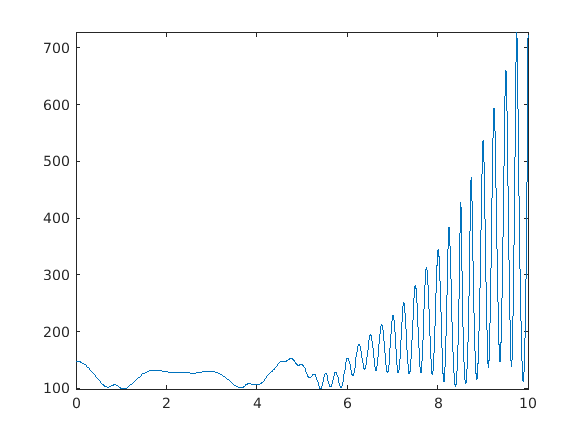

% Question 5
fplot(anormal, [0, 10]);

% TODO solve for the value analytically

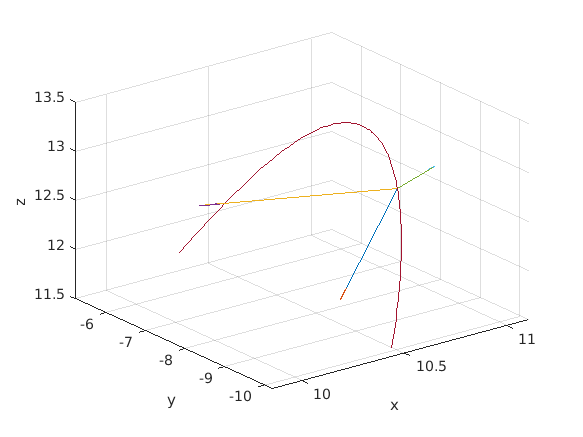

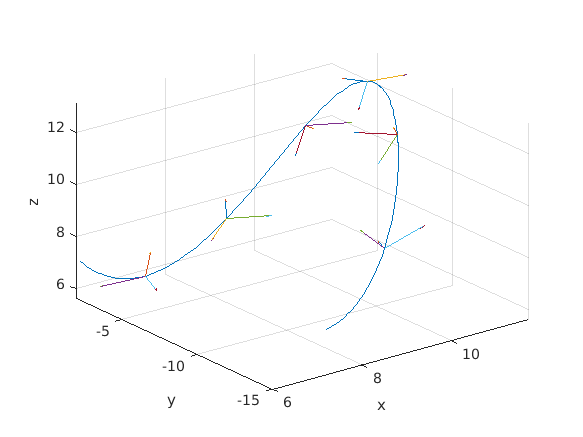

% Question 6
time=9.05;


% Evaluate symbolic functions in the given time
Tv=vpa(subs(T, t, time));
Nv=vpa(subs(N, t, time));
Bv=vpa(subs(B, t, time));
pos=vpa(subs(r, t, time));
av=vpa(subs(aunit, t, time));

% Part A
% Plot the three vectors [TODO Make look cleaner]
plotvector(pos, pos + Tv);
hold on
plotvector(pos, pos + Nv);
hold on
plotvector(pos, pos + Bv);
hold on
fplot3(r(:,1), r(:,2), r(:,3), [8.9333333, 9.0933333]);
hold off

% Part B
fplot3(r(:,1), r(:,2), r(:,3), [520/60, 555/60]);
hold on
for i=525/60:5/60:550/60
    plotvector(subs(r, t, i), subs(T + r, t, i));
    hold on
    plotvector(subs(r, t, i), subs(N + r, t, i));
    hold on
    plotvector(subs(r, t, i), subs(B + r, t, i));
    hold on
end
hold off


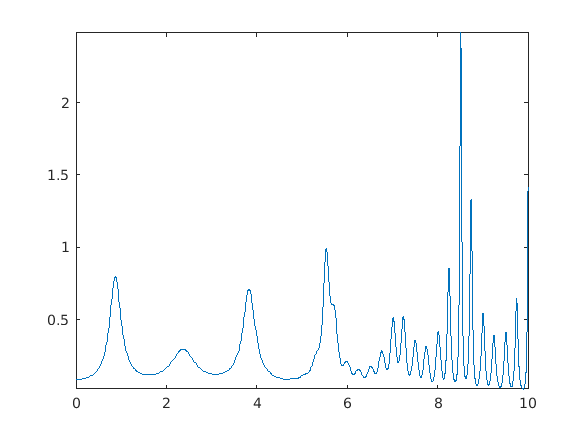

% Question 7 [these work, just take a long time]
% TODO Solve for curvature analytically
fplot(curvature,[0, 10]);

% Question 8
%fplot(torsion,[0,10]); 

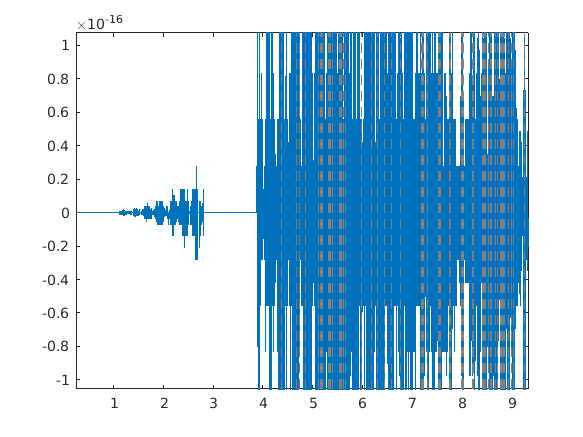

% PART B
rm1 = 5+sin(t);
rm2 = 2*cos(t);
rm3 = 3*sqrt(t);

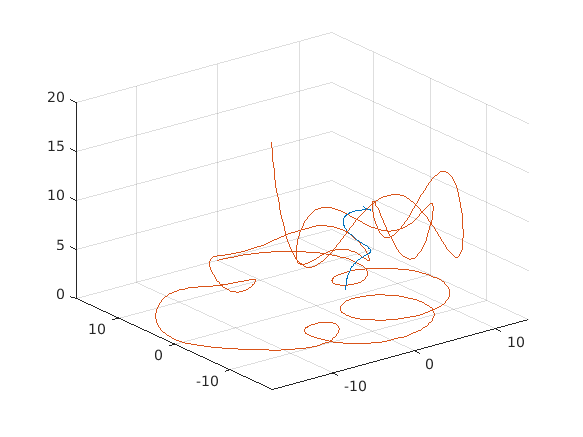

fplot3(rm1, rm2, rm3, [0, 10]);
hold on
fplot3(fx, fy, fz, [0, 10]);
hold off
